 文字提取与识别

图像预处理

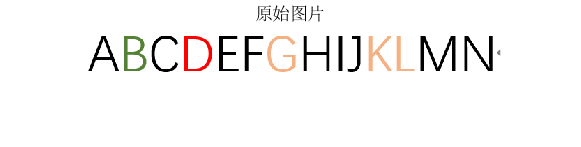

I_RGB = imread("words.png");
figure;imshow(I_RGB);title("原始图片");

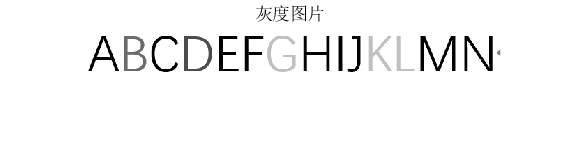

% 彩转灰
I_GRAY = rgb2gray(I_RGB);  
figure;imshow(I_GRAY);title("灰度图片");

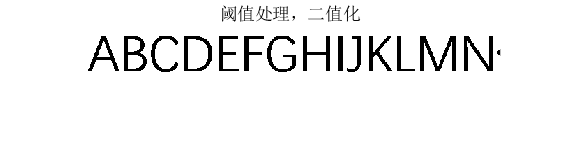

% 阈值分割,使用 Otsu 方法计算全局图像阈值，最大类间方差法
% thresh = graythresh(I_GRAY);
% I_THRESH = im2bw(I_GRAY,thresh);
% I_THRESH = imbinarize(I_GRAY);  %默认使用Otsu方法,有字符被去除
% I_THRESH = imbinarize(I_GRAY,'adaptive','Sensitivity',0.62);
I_THRESH = imbinarize(I_GRAY,0.9);

figure;imshow(I_THRESH);title("阈值处理，二值化");

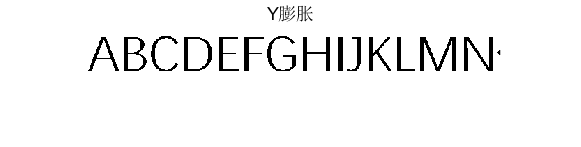

% 腐蚀膨胀处理，相对亮的区域来说
% 膨胀，使白色区域扩大；
% 腐蚀，使黑色区域扩大；
% Y方向腐蚀
Seed_Y= [1;1;1];
I_TEMP = imdilate(I_THRESH,Seed_Y);
figure;imshow(I_TEMP);title("Y膨胀");

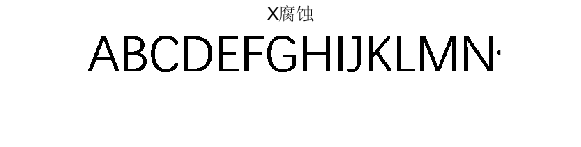

I_TEMP = imerode(I_TEMP,Seed_Y);
figure;imshow(I_TEMP);title("Y腐蚀");

% X方向腐蚀
Seed_X = [1 1 1];
I_TEMP = imdilate(I_TEMP,Seed_X);
figure;imshow(I_TEMP);title("X膨胀");
I_TEMP = imerode(I_TEMP,Seed_X);
figure;imshow(I_TEMP);title("X腐蚀");

% 预处理结果
I_PRE = I_TEMP;

字符提取

反色和截取

由于使用的图片是非常标准的，每个字符都连在一起，可以直接用行为零或者列为零作为图像的分隔标准。

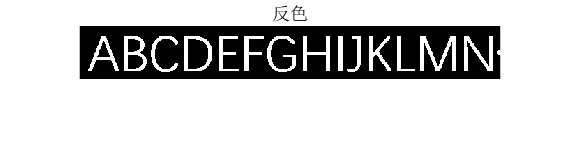

% 反色
I_REGION = (I_PRE ~= 1);
figure;imshow(I_REGION);title("反色");

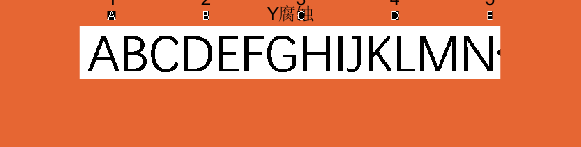

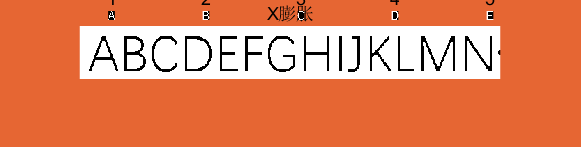

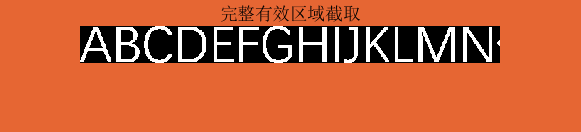

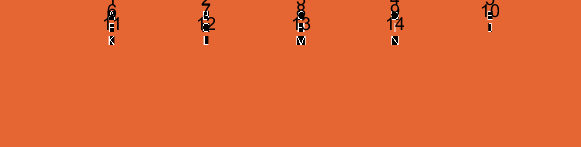

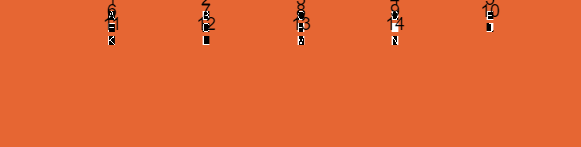


% 区域提取函数（和前面的功能重复了）
I_CUT = cutting(I_REGION);
figure;imshow(I_CUT);title("完整有效区域截取");
% 提取字符
k=0; 
while size(I_CUT,2) > 10
    [word{k+1},I_CUT] = getting(I_CUT);
    k = k+1;
end
cnt = k;


for j = 1:cnt    
    set(gcf,'color',[0.9 0.4 0.2]);%任意RGB色 如果背景是白色的话，会和字符的颜色掺和在一起
    figure(5);subplot(10,5,j);imshow(word{j});title(int2str(j));
    word{j} = imresize(word{j},[40,30]);
    set(gcf,'color',[0.9 0.4 0.2]);%任意RGB色 如果背景是白色的话，会和字符的颜色掺和在一起
    figure(6),subplot(10,5,j);imshow(word{j});title(int2str(j));
end

字符库制作

采用与字符分割相同的方式获取单个字符，进行标注

chars = getting_chars_from_file("characters.png");
for i = 1 : size(chars,2)
    name = sprintf("./characters/%c.png",i+64);
    %name = strcat(int2str(i+64),".png");
    imwrite(chars{i},name);
end

字符匹配及结果

codecollection = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ';

for p=1:cnt
    alarm = zeros(1,26);
    for o = 1:26
        filename = sprintf("./characters/%c.png",o+'A'-1);
        refer = imread(filename);
        %refer = im2bw(refer);
        for i=1:40
            for j = 1:30
                if(word{p}(i,j)) == refer(i,j)
                    alarm(1,o) = alarm(1,o)+1;
                end
            end
        end

        number = 1;
        for q = 1:26
            if alarm(1,q) > alarm(1,number)
                number = q;
            end
        end
        final(1,p) = codecollection(number);
    end
end
final

final = 'ABCDEFGHIJKLMN'

封装识别接口和测试

final = character_recognition("characters.png")

final = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ'

final = character_recognition("hello.png")

final = 'HELLO'

final = character_recognition("matlab.png")

final = 'MATLAB'

function y=cutting(I)   % 获取图像的有效数据区域（多个字符或者单个字符均可使用）
[m,n] = size(I);
top = 1;
bottom = m;
left =1;
right = n;
while sum(I(top,:)) == 0 && top < m
    top = top+1;
end
while sum(I(bottom,:)) == 0 && bottom >= 1
    bottom = bottom - 1;
end
while sum(I(:,left)) == 0 &&  left<n
    left = left+1;
end
while sum(I(:,right)) == 0 && right >= 1
    right = right -1;
end
height = bottom - top;
width = right - 1;
y = imcrop(I,[left,top,width,height]);
end

function [word,result] = getting(I)
word = [];
flag = 0;
y1 = 8;
y2 = 0.5;
% word:字符矩阵、flag：标志位、y1/y2:字符大小阈值
while flag == 0
    [m,n] = size(I);
    wide = 0;
    
    if m==0 | n==0  % 无空余字符，提取完毕
        break;
    end
    % 从左至右寻找为0的列作为分割线，由于前面的处理左侧肯定不为零
    while  (sum(I(:,wide+1)) ~= 0  && wide <= n-2 ) 
        wide = wide + 1;
    end
    
    % 裁剪出第一个字符区域
    temp = cutting(imcrop(I,[1,1,wide,m]));
    [m1,n1] = size(temp);
    if wide < y1 && n1/m1 > y2  %判断是否是一个字符
        I(:,1:wide) = 0;        %判定为无效字符，清零，下面肯定是零
        if sum(sum(I)) ~= 0     %不为零，说明还有字符
            I = cutting(I);
            flag = 1;
        else                    %为零，说明没有字符
            word = []; 
            flag = 1;
        end
    else
        word = cutting(imcrop(I,[1,1,wide,m]));     %有效字符，提取
        I(:,1:wide) = 0;
        if sum(sum(I)) ~= 0
            I = cutting(I);
            flag =  1;
        else
            I = [];
        end
    end
end
result = I;
end

function words = getting_chars_from_file(filename)

I_RGB = imread(filename);
% 彩转灰
I_GRAY = rgb2gray(I_RGB); 
I_THRESH = imbinarize(I_GRAY,0.9);

% 腐蚀膨胀处理，相对亮的区域来说
% 膨胀，使白色区域扩大；
% 腐蚀，使黑色区域扩大；
% Y方向腐蚀
Seed_Y= [1;1;1];
I_TEMP = imdilate(I_THRESH,Seed_Y);
I_TEMP = imerode(I_TEMP,Seed_Y);
% X方向腐蚀
Seed_X = [1 1 1];
I_TEMP = imdilate(I_TEMP,Seed_X);
I_TEMP = imerode(I_TEMP,Seed_X);

% 预处理结果
I_PRE = I_TEMP;

% 反色
I_REGION = (I_PRE ~= 1);

% 区域提取函数（和前面的功能重复了）
I_CUT = cutting(I_REGION);

% 提取字符

k=0; %Wmax: 字符集最大容量
while size(I_CUT,2) > 10
    [words{k+1},I_CUT] = getting(I_CUT);
    k = k+1;
end

% 大小标准化
cnt = k;
for j = 1:cnt    
    words{j} = imresize(words{j},[40,30]);
end

end


function  final = character_recognition(filename)
codecollection = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ';
word = getting_chars_from_file(filename);
cnt = size(word,2);
for p=1:cnt
    alarm = zeros(1,26);
    for o = 1:26
        char_name = sprintf("./characters/%c.png",o+'A'-1);
        refer = imread(char_name);
        %refer = im2bw(refer);
        for i=1:40
            for j = 1:30
                if(word{p}(i,j)) == refer(i,j)
                    alarm(1,o) = alarm(1,o)+1;
                end
            end
        end

        number = 1;
        for q = 1:26
            if alarm(1,q) > alarm(1,number)
                number = q;
            end
        end
        final(1,p) = codecollection(number);
    end
end
end